# EXP_FSERIES

Calculates the Exponential Fourier for a Square Wave with Odd Symmetry

clear all
%

## Set up parameters

syms t A;
u0(t) = heaviside(t)

$$u0(t) = \mathrm{heaviside}\left(t\right)$$

## Set up problem

f0 = 1000;         % Hz
T0 = 1/f0;          % s
omega_0 = 2*pi/T0; % rad/s

## Specify which harmonics we want

k_max = 11;

## Define f(t)

!!!IMPORTANT!!!: the signal definition must cover [0 to T0]

So I've sythesized two periods so we can easily shift the waveform later. 

It's a good idea to plot the waveform so you can check it's OK!

% first period
f(t) = A*(u0(t)-u0(t-T0/2)) - A*(u0(t-T0/2) - u0(t-T0));
% Add second period - f(t) delayed by T0
f(t) = f(t) + f(t-T0)

$$f(t) = A\,\left(\mathrm{heaviside}\left(t-\frac{1}{500}\right)-\mathrm{heaviside}\left(t-\frac{3}{2000}\right)\right)-A\,\left(\mathrm{heaviside}\left(t-\frac{1}{2000}\right)-\mathrm{heaviside}\left(t\right)\right)+A\,\left(\mathrm{heaviside}\left(t-\frac{1}{1000}\right)-\mathrm{heaviside}\left(t-\frac{1}{2000}\right)\right)+A\,\left(\mathrm{heaviside}\left(t-\frac{1}{1000}\right)-\mathrm{heaviside}\left(t-\frac{3}{2000}\right)\right)$$

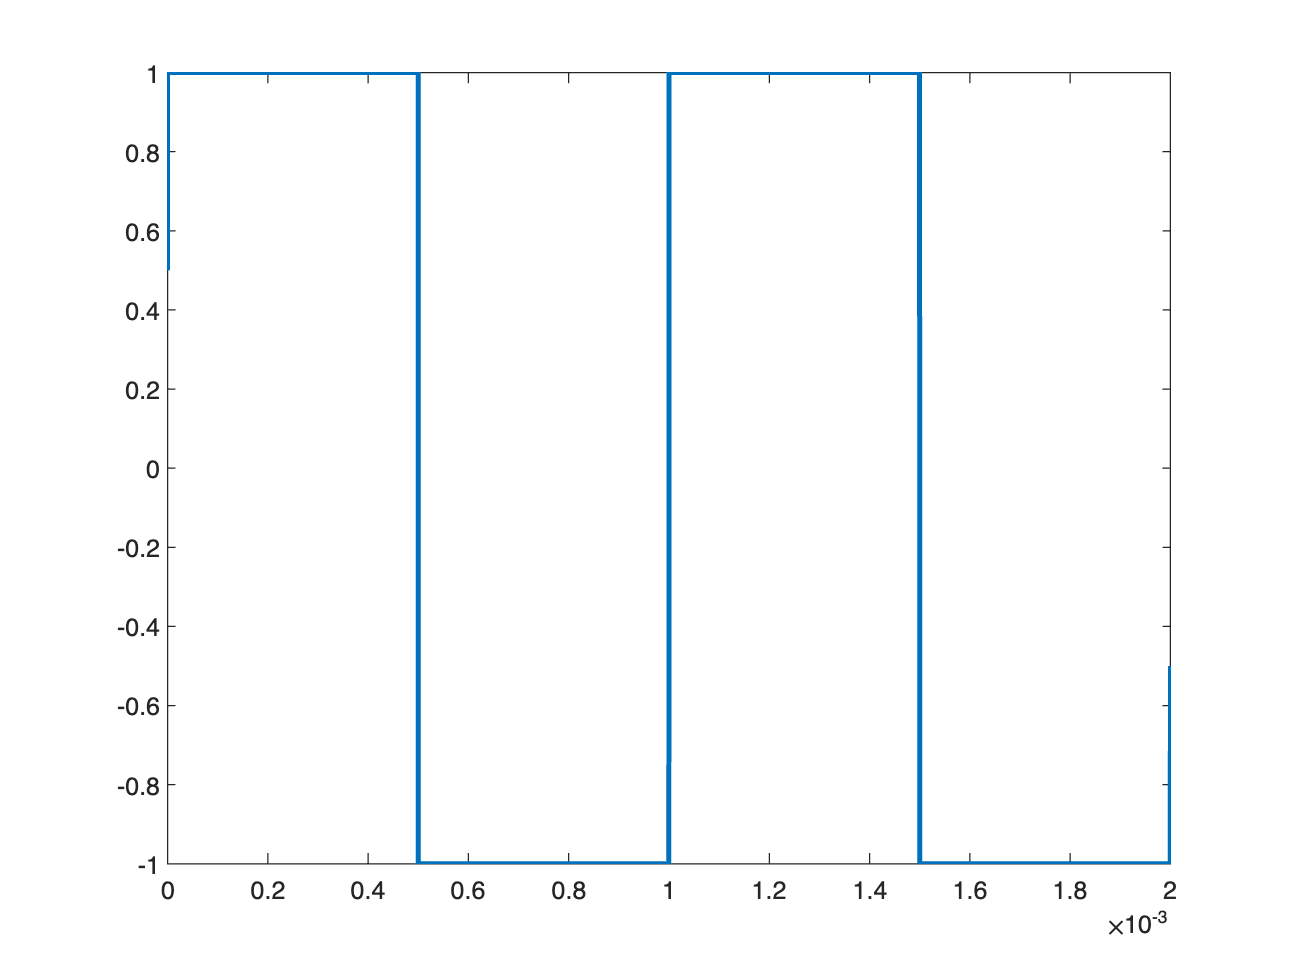

fplot(subs(f(t),A,1),[0,2*T0],'LineWidth',2)

## Compute EFS

[Ck, w] = FourierSeries(f(t), T0, k_max);
Ck

$$Ck = \begin{array}{l} \left(\begin{array}{ccccccccccccccccccccccc} \sigma_{1} & 0 & \sigma_{2} & 0 & \sigma_{3} & 0 & \sigma_{4} & 0 & \sigma_{5} & 0 & \frac{2\,A\,\mathrm{i}}{\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{\pi } & 0 & -\sigma_{5} & 0 & -\sigma_{4} & 0 & -\sigma_{3} & 0 & -\sigma_{2} & 0 & -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,A\,\mathrm{i}}{11\,\pi }\\ \sigma_{2}=\frac{2\,A\,\mathrm{i}}{9\,\pi }\\ \sigma_{3}=\frac{2\,A\,\mathrm{i}}{7\,\pi }\\ \sigma_{4}=\frac{2\,A\,\mathrm{i}}{5\,\pi }\\ \sigma_{5}=\frac{2\,A\,\mathrm{i}}{3\,\pi } \end{array}$$

## Reconstruct f(t) from expontial functions

Ft = 0;
for k=1:length(Ck)
    Ft = Ft + Ck(k)*exp(j*w(k)*t);
end
Ft = vpa(Ft,4)

$$Ft = 0.05787\,A\,{\mathrm{e}}^{-69120.0\,t\,\mathrm{i}}\,\mathrm{i}-0.05787\,A\,{\mathrm{e}}^{69120.0\,t\,\mathrm{i}}\,\mathrm{i}+0.2122\,A\,{\mathrm{e}}^{-18850.0\,t\,\mathrm{i}}\,\mathrm{i}-0.2122\,A\,{\mathrm{e}}^{18850.0\,t\,\mathrm{i}}\,\mathrm{i}+0.09095\,A\,{\mathrm{e}}^{-43980.0\,t\,\mathrm{i}}\,\mathrm{i}-0.09095\,A\,{\mathrm{e}}^{43980.0\,t\,\mathrm{i}}\,\mathrm{i}+0.6366\,A\,{\mathrm{e}}^{-6283.0\,t\,\mathrm{i}}\,\mathrm{i}-0.6366\,A\,{\mathrm{e}}^{6283.0\,t\,\mathrm{i}}\,\mathrm{i}+0.07074\,A\,{\mathrm{e}}^{-56550.0\,t\,\mathrm{i}}\,\mathrm{i}-0.07074\,A\,{\mathrm{e}}^{56550.0\,t\,\mathrm{i}}\,\mathrm{i}+0.1273\,A\,{\mathrm{e}}^{-31420.0\,t\,\mathrm{i}}\,\mathrm{i}-0.1273\,A\,{\mathrm{e}}^{31420.0\,t\,\mathrm{i}}\,\mathrm{i}$$

## plot the numerical results from Matlab calculation

Convert symbolic to numeric result

Ck_num = subs(Ck,A,1);
Ck_num = vpa(Ck_num, 4);

## plot

note we need to convert to double

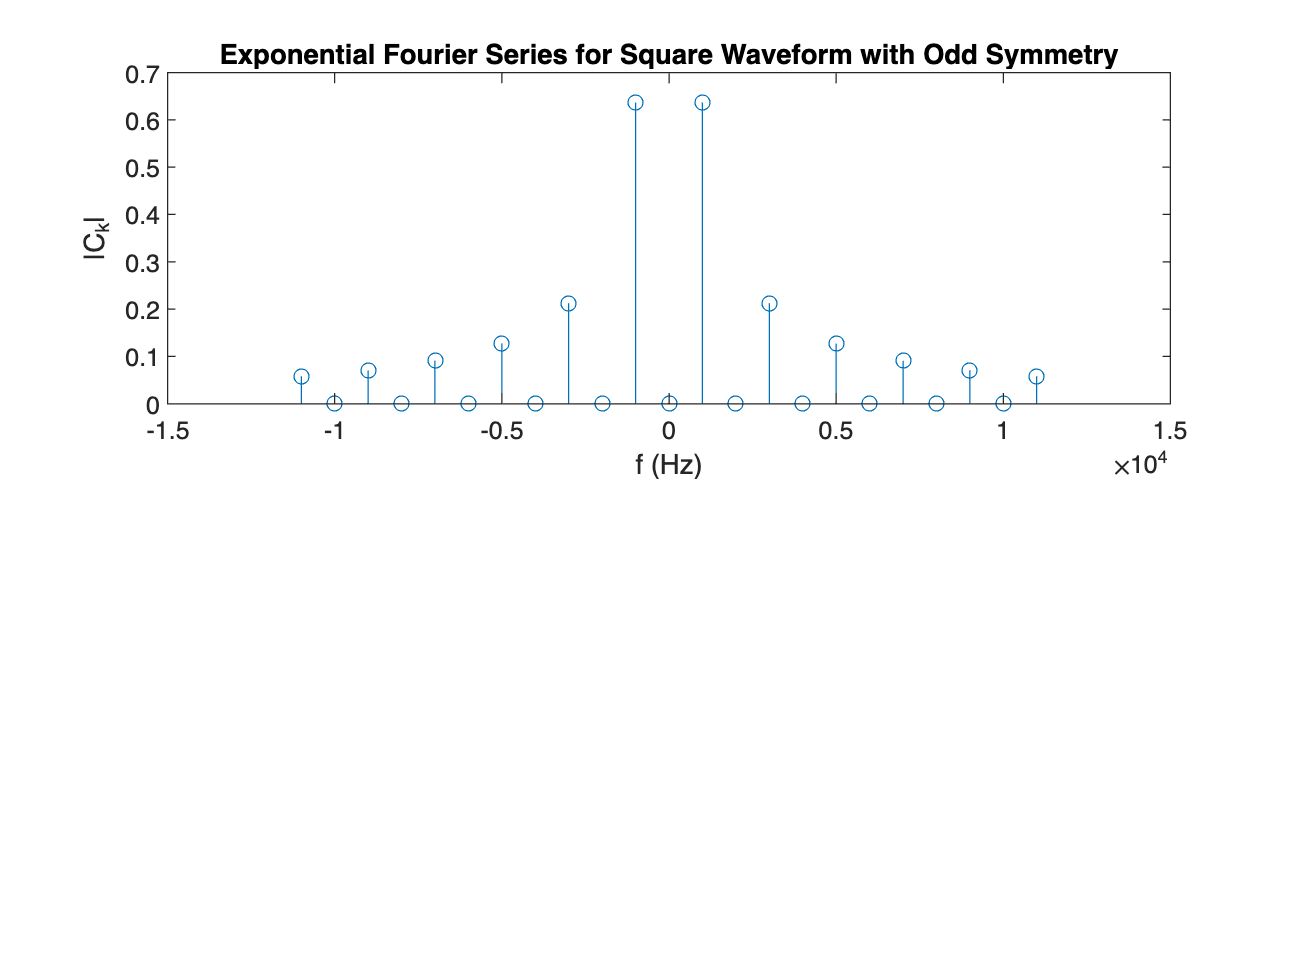

subplot(211)
stem(w/(2*pi),abs(double(Ck_num)), 'o-');
title('Exponential Fourier Series for Square Waveform with Odd Symmetry')
xlabel('f (Hz)');
ylabel('|C_k|');

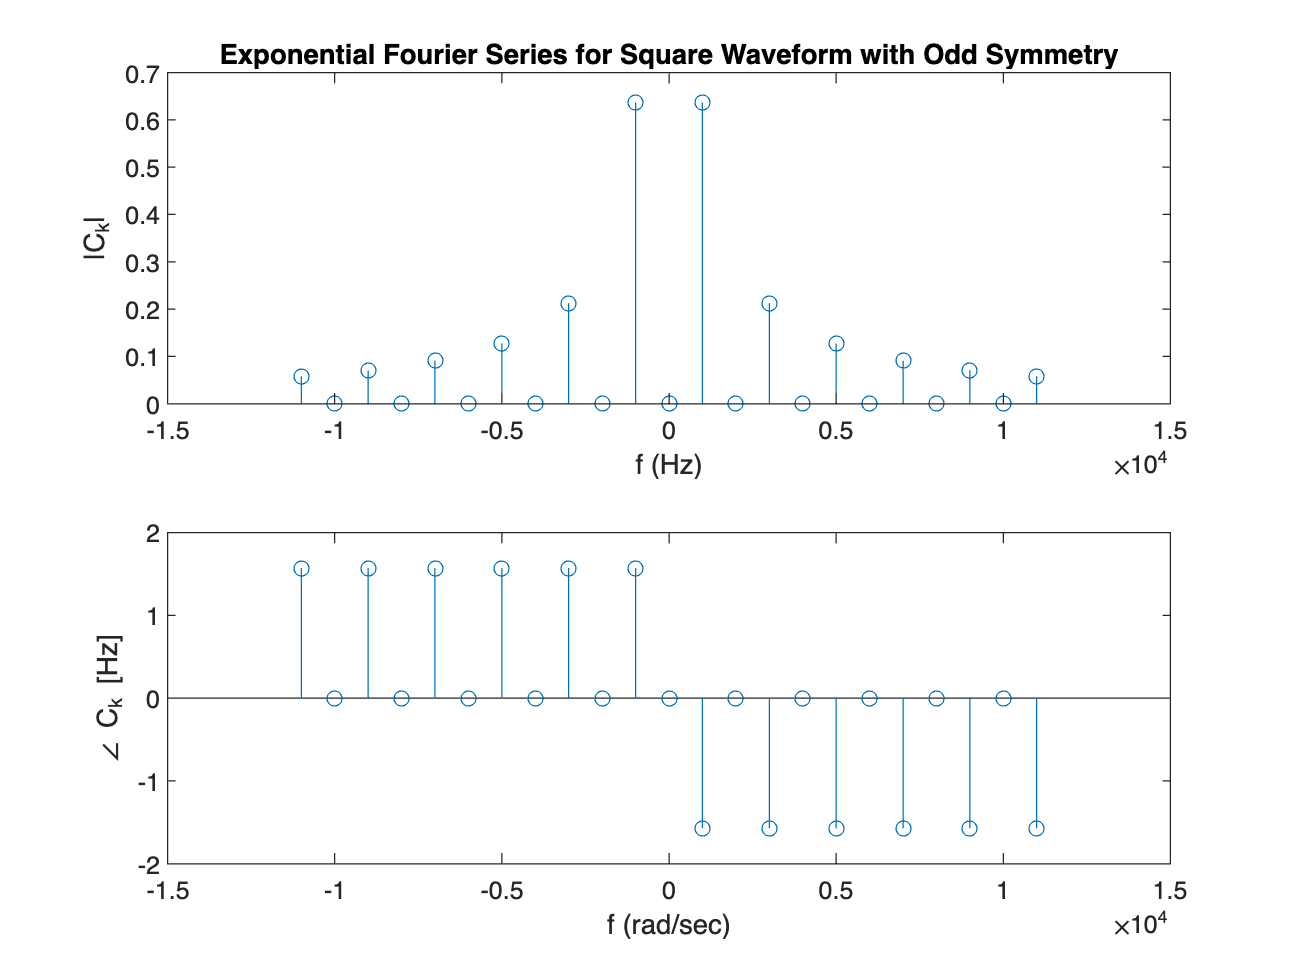

subplot(212)
stem(w/(2*pi),angle(double(Ck_num)), 'o-');
xlabel('f (rad/sec)');
ylabel('\angle C_k [Hz]');